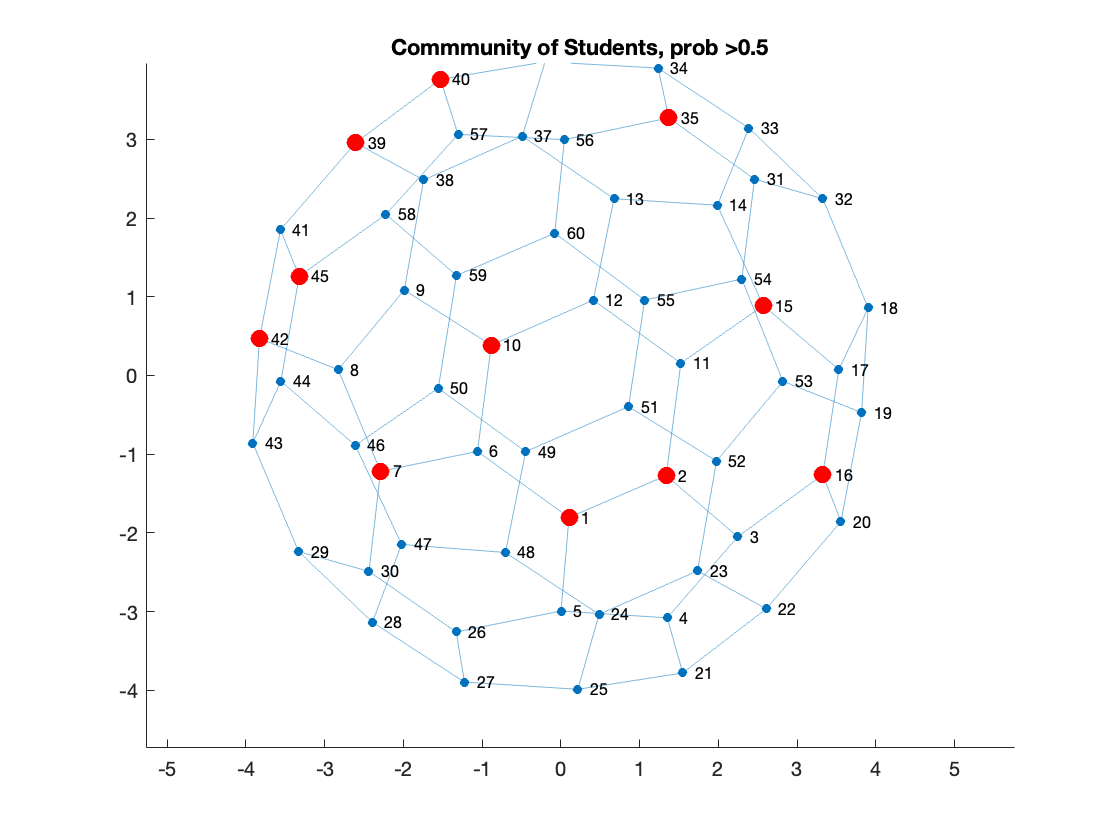

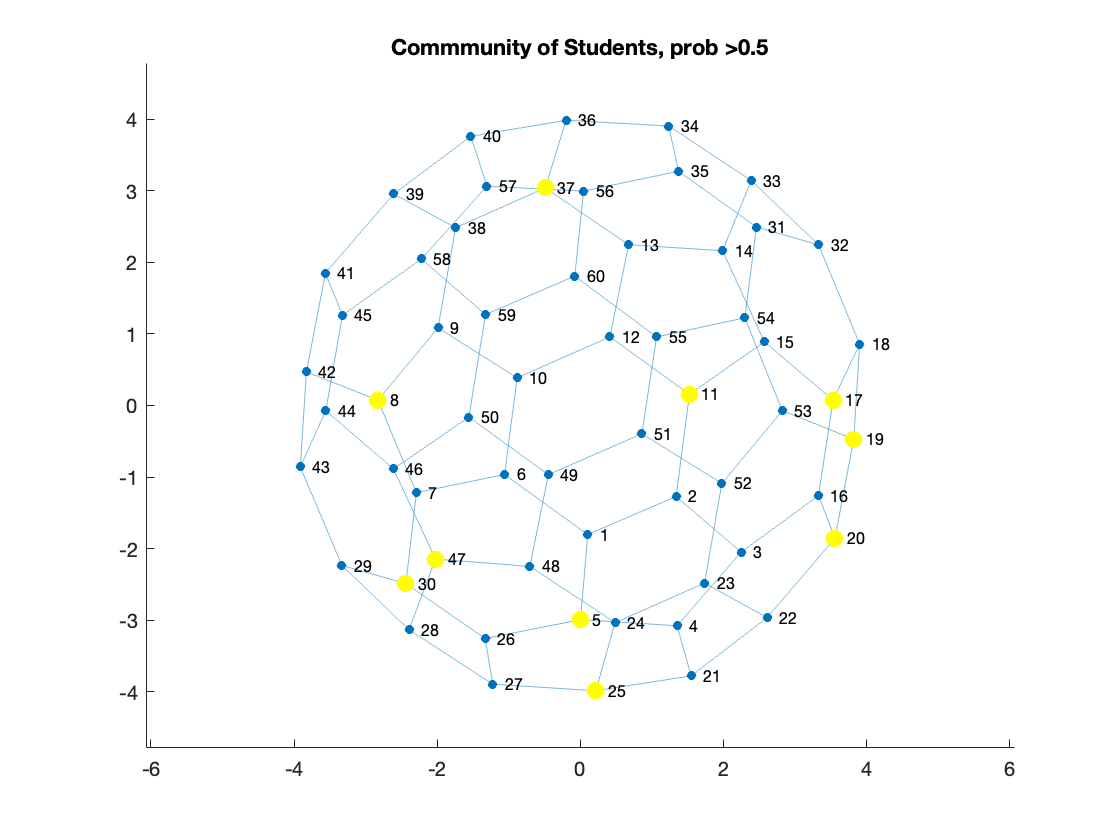

% Generate binary cell
binary_prob = [];
for i=1:kc
    b = normalized_prob_of_nodes{1,i};
    c = b > 0.5;
    binary_prob = [binary_prob, c];
end

% Loop over binary_prob values
color = ["r","y"];
for x = 1:kc
    % Create graph and plot
    figure;
    [B,V] = bucky;
    G = graph(B);
    axis equal;
    hold on;
    
    % Example binary cell
    binaryCell = binary_prob(:, x);
    
    % Find nodes marked as 1 in binary cell
    markedNodes = find(binaryCell == 1);
    
    % Plot graph
    p = plot(G); % Create a new GraphPlot object for each graph
    
    % Highlight the marked nodes with different colors
    for i = 1:numel(markedNodes)
        % Change the node color based on the value of x
        c = color(x);
        highlight(p, markedNodes(i), 'NodeColor', c, 'MarkerSize', 8);
    end
    title("Commmunity of Students, prob >0.5")
    hold off;
end